# Project 1 - Shaper Mechanism Kinematic and Kinetic Functions

Austin Lew

Alyzen Jeraj

Edwin Giang

## Kinematic Functions

### Global Constants

theta2 = 0:0.01:2*pi; % Our single independant variable (input)
d1theta2 = (135./60).*2.*pi; % Anglular velocity of theta2 (rad./s)

% Lengths
r2 = 5; % cm
r4 = 16; % cm
r6 = 8; % cm
r7 = -15; % cm
r8 = -4; % cm

% Mass
m2 = 2.7.*(pi.*0.25.^2).*5; % gram
m3 = 2.7.*(pi.*0.25.^2).*16; % gram
m6 = 2.7.*(pi.*0.25.^2).*8; % gram

% Moment of inertia
I3 = 1./4.*m3.*(0.5).^2 + 1./12.*m3.*(16).^2; % MOI about center, g*cm^2
I6 = 1./4.*m3.*(0.5).^2 + 1./3.*m3.*(8).^2; % MOI about end, g*cm^2

*Write a MATLAB code to plot the abovementioned kinematic functions vs the input angle θ2.*

### Loop 1

#### theta4

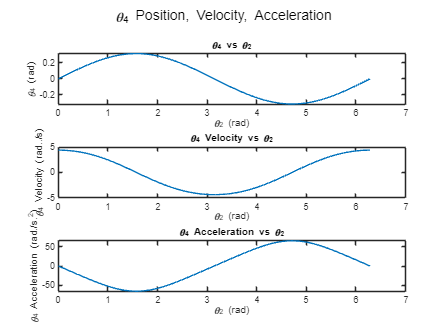

% Theta4 displacement, velocity, and acceleration
theta4 = asin((r2.*sin(theta2)./r4));
d1theta4 = (45.*pi.*cos(theta2))./(32.*(1 - (25.*sin(theta2).^2)./256).^(1./2));
d2theta4 = -(9.*pi.*((45.*pi.*sin(theta2))./(32.*(1 - (25.*sin(theta2).^2)./256).^(1./2)) - (1125.*pi.*cos(theta2).^2.*sin(theta2))./(8192.*(1 - (25.*sin(theta2).^2)./256).^(3./2))))./2;

% Plotting
figure(1);
subplot(3,1,1);
plot(theta2, theta4);
title("\theta_4 vs \theta_2");
xlabel("\theta_2 (rad)");
ylabel("\theta_4 (rad)");

subplot(3,1,2);
plot(theta2, d1theta4);
title("\theta_4 Velocity vs \theta_2");
xlabel("\theta_2 (rad)");
ylabel("\theta_4 Velocity (rad../s)");

subplot(3,1,3);
plot(theta2, d2theta4);
title("\theta_4 Acceleration vs \theta_2");
xlabel("\theta_2 (rad)");
ylabel("\theta_4 Acceleration (rad./s.^2)");
sgtitle("\theta_4 Position, Velocity, Acceleration");

#### r3

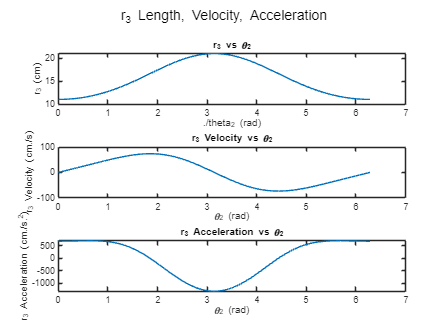

% r3 length, velocity and acceleration
r3 = r4.*cos(theta4)- r2.*cos(theta2);
d1r3 = (9.*pi.*(5.*sin(theta2) - (25.*cos(theta2).*sin(theta2))./(16.*(1 - (25.*sin(theta2).^2)./256).^(1./2))))./2;
d2r3 = (81.*pi.^2.*(5.*cos(theta2) + (25.*sin(theta2).^2)./(16.*(1 - (25.*sin(theta2).^2)./256).^(1./2)) - (25.*cos(theta2).^2)./(16.*(1 - (25.*sin(theta2).^2)./256).^(1./2)) - (625.*cos(theta2).^2.*sin(theta2).^2)./(4096.*(1 - (25.*sin(theta2).^2)./256).^(3./2))))./4;

% Plotting
figure(2);
subplot(3,1,1);
plot(theta2, r3);
title("r_3 vs \theta_2");
xlabel("./theta_2 (rad)");
ylabel("r_3 (cm)");

subplot(3,1,2);
plot(theta2, d1r3);
title("r_3 Velocity vs \theta_2");
xlabel("\theta_2 (rad)");
ylabel("r_3 Velocity (cm./s)");

subplot(3,1,3);
plot(theta2, d2r3);
title("r_3 Acceleration vs \theta_2");
xlabel("\theta_2 (rad)");
ylabel("r_3 Acceleration (cm./s.^2)");

sgtitle("r_3 Length, Velocity, Acceleration");

### Loop 2

#### theta6

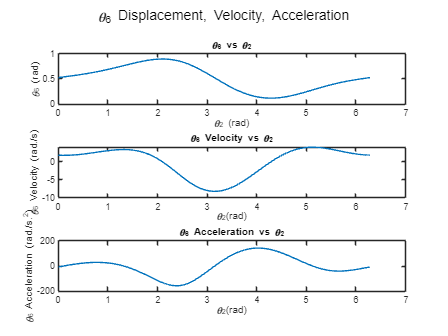

% theta3 displacement, velocity and acceleration
theta6 = asin((r2.*sin(theta2-theta4)+r7.*sin(theta4)-r8.*cos(theta4))./r6) + theta4;
d1theta6 = (9.*pi.*((5.*cos(theta2))./(16.*(1 - (25.*sin(theta2).^2)./256).^(1./2)) - ((75.*cos(theta2))./128 + (5.*cos(theta2 - asin((5.*sin(theta2))./16)).*((5.*cos(theta2))./(16.*(1 - (25.*sin(theta2).^2)./256).^(1./2)) - 1))./8 + (25.*cos(theta2).*sin(theta2))./(512.*(1 - (25.*sin(theta2).^2)./256).^(1./2)))./(1 - ((5.*sin(theta2 - asin((5.*sin(theta2))./16)))./8 - (75.*sin(theta2))./128 + (1 - (25.*sin(theta2).^2)./256).^(1./2)./2).^2).^(1./2)))./2;
d2theta6 = (81.*pi.^2.*(((75.*sin(theta2))./128 - (5.*sin(theta2 - asin((5.*sin(theta2))./16)).*((5.*cos(theta2))./(16.*(1 - (25.*sin(theta2).^2)./256).^(1./2)) - 1).^2)./8 + (25.*sin(theta2).^2)./(512.*(1 - (25.*sin(theta2).^2)./256).^(1./2)) + (5.*cos(theta2 - asin((5.*sin(theta2))./16)).*((5.*sin(theta2))./(16.*(1 - (25.*sin(theta2).^2)./256).^(1./2)) - (125.*cos(theta2).^2.*sin(theta2))./(4096.*(1 - (25.*sin(theta2).^2)./256).^(3./2))))./8 - (25.*cos(theta2).^2)./(512.*(1 - (25.*sin(theta2).^2)./256).^(1./2)) - (625.*cos(theta2).^2.*sin(theta2).^2)./(131072.*(1 - (25.*sin(theta2).^2)./256).^(3./2)))./(1 - ((5.*sin(theta2 - asin((5.*sin(theta2))./16)))./8 - (75.*sin(theta2))./128 + (1 - (25.*sin(theta2).^2)./256).^(1./2)./2).^2).^(1./2) - (5.*sin(theta2))./(16.*(1 - (25.*sin(theta2).^2)./256).^(1./2)) + (((5.*sin(theta2 - asin((5.*sin(theta2))./16)))./8 - (75.*sin(theta2))./128 + (1 - (25.*sin(theta2).^2)./256).^(1./2)./2).*((75.*cos(theta2))./128 + (5.*cos(theta2 - asin((5.*sin(theta2))./16)).*((5.*cos(theta2))./(16.*(1 - (25.*sin(theta2).^2)./256).^(1./2)) - 1))./8 + (25.*cos(theta2).*sin(theta2))./(512.*(1 - (25.*sin(theta2).^2)./256).^(1./2))).^2)./(1 - ((5.*sin(theta2 - asin((5.*sin(theta2))./16)))./8 - (75.*sin(theta2))./128 + (1 - (25.*sin(theta2).^2)./256).^(1./2)./2).^2).^(3./2) + (125.*cos(theta2).^2.*sin(theta2))./(4096.*(1 - (25.*sin(theta2).^2)./256).^(3./2))))./4;

% Plotting
figure(3);
subplot(3,1,1);
plot(theta2, theta6);
title("\theta_6 vs \theta_2");
xlabel("\theta_2 (rad)");
ylabel("\theta_6 (rad)");

subplot(3,1,2);
plot(theta2, d1theta6);
title("\theta_6 Velocity vs \theta_2");
xlabel("\theta_2(rad)");
ylabel("\theta_6 Velocity (rad./s)");

subplot(3,1,3);
plot(theta2, d2theta6);
title("\theta_6 Acceleration vs \theta_2");
xlabel("\theta_2(rad)");
ylabel("\theta_6 Acceleration (rad./s.^2)");

sgtitle("\theta_6 Displacement, Velocity, Acceleration");

#### r5

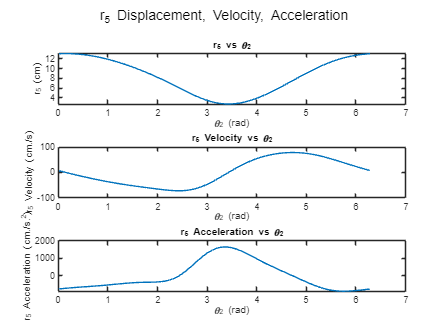

% r5 displacement, velocity and acceleration
r5 = (r2.*sin(theta2) - r6.*sin(theta6) - r8)./sin(theta4);
d1r5 = (9.*pi.*((16.*(5.*cos(theta2) - 8.*cos(asin((5.*sin(theta2 - asin((5.*sin(theta2))./16)))./8 - (75.*sin(theta2))./128 + (1 - (25.*sin(theta2).^2)./256).^(1./2)./2) + asin((5.*sin(theta2))./16)).*((5.*cos(theta2))./(16.*(1 - (25.*sin(theta2).^2)./256).^(1./2)) - ((75.*cos(theta2))./128 + (5.*cos(theta2 - asin((5.*sin(theta2))./16)).*((5.*cos(theta2))./(16.*(1 - (25.*sin(theta2).^2)./256).^(1./2)) - 1))./8 + (25.*cos(theta2).*sin(theta2))./(512.*(1 - (25.*sin(theta2).^2)./256).^(1./2)))./(1 - ((5.*sin(theta2 - asin((5.*sin(theta2))./16)))./8 - (75.*sin(theta2))./128 + (1 - (25.*sin(theta2).^2)./256).^(1./2)./2).^2).^(1./2))))./(5.*sin(theta2)) - (16.*cos(theta2).*(5.*sin(theta2) - 8.*sin(asin((5.*sin(theta2 - asin((5.*sin(theta2))./16)))./8 - (75.*sin(theta2))./128 + (1 - (25.*sin(theta2).^2)./256).^(1./2)./2) + asin((5.*sin(theta2))./16)) + 4))./(5.*sin(theta2).^2)))./2;
d2r5 = -(81.*pi.^2.*((16.*(5.*sin(theta2) - 8.*sin(asin((5.*sin(theta2 - asin((5.*sin(theta2))./16)))./8 - (75.*sin(theta2))./128 + (1 - (25.*sin(theta2).^2)./256).^(1./2)./2) + asin((5.*sin(theta2))./16)).*((5.*cos(theta2))./(16.*(1 - (25.*sin(theta2).^2)./256).^(1./2)) - ((75.*cos(theta2))./128 + (5.*cos(theta2 - asin((5.*sin(theta2))./16)).*((5.*cos(theta2))./(16.*(1 - (25.*sin(theta2).^2)./256).^(1./2)) - 1))./8 + (25.*cos(theta2).*sin(theta2))./(512.*(1 - (25.*sin(theta2).^2)./256).^(1./2)))./(1 - ((5.*sin(theta2 - asin((5.*sin(theta2))./16)))./8 - (75.*sin(theta2))./128 + (1 - (25.*sin(theta2).^2)./256).^(1./2)./2).^2).^(1./2)).^2 + 8.*cos(asin((5.*sin(theta2 - asin((5.*sin(theta2))./16)))./8 - (75.*sin(theta2))./128 + (1 - (25.*sin(theta2).^2)./256).^(1./2)./2) + asin((5.*sin(theta2))./16)).*(((75.*sin(theta2))./128 - (5.*sin(theta2 - asin((5.*sin(theta2))./16)).*((5.*cos(theta2))./(16.*(1 - (25.*sin(theta2).^2)./256).^(1./2)) - 1).^2)./8 + (25.*sin(theta2).^2)./(512.*(1 - (25.*sin(theta2).^2)./256).^(1./2)) + (5.*cos(theta2 - asin((5.*sin(theta2))./16)).*((5.*sin(theta2))./(16.*(1 - (25.*sin(theta2).^2)./256).^(1./2)) - (125.*cos(theta2).^2.*sin(theta2))./(4096.*(1 - (25.*sin(theta2).^2)./256).^(3./2))))./8 - (25.*cos(theta2).^2)./(512.*(1 - (25.*sin(theta2).^2)./256).^(1./2)) - (625.*cos(theta2).^2.*sin(theta2).^2)./(131072.*(1 - (25.*sin(theta2).^2)./256).^(3./2)))./(1 - ((5.*sin(theta2 - asin((5.*sin(theta2))./16)))./8 - (75.*sin(theta2))./128 + (1 - (25.*sin(theta2).^2)./256).^(1./2)./2).^2).^(1./2) - (5.*sin(theta2))./(16.*(1 - (25.*sin(theta2).^2)./256).^(1./2)) + (((5.*sin(theta2 - asin((5.*sin(theta2))./16)))./8 - (75.*sin(theta2))./128 + (1 - (25.*sin(theta2).^2)./256).^(1./2)./2).*((75.*cos(theta2))./128 + (5.*cos(theta2 - asin((5.*sin(theta2))./16)).*((5.*cos(theta2))./(16.*(1 - (25.*sin(theta2).^2)./256).^(1./2)) - 1))./8 + (25.*cos(theta2).*sin(theta2))./(512.*(1 - (25.*sin(theta2).^2)./256).^(1./2))).^2)./(1 - ((5.*sin(theta2 - asin((5.*sin(theta2))./16)))./8 - (75.*sin(theta2))./128 + (1 - (25.*sin(theta2).^2)./256).^(1./2)./2).^2).^(3./2) + (125.*cos(theta2).^2.*sin(theta2))./(4096.*(1 - (25.*sin(theta2).^2)./256).^(3./2)))))./(5.*sin(theta2)) - (16.*(5.*sin(theta2) - 8.*sin(asin((5.*sin(theta2 - asin((5.*sin(theta2))./16)))./8 - (75.*sin(theta2))./128 + (1 - (25.*sin(theta2).^2)./256).^(1./2)./2) + asin((5.*sin(theta2))./16)) + 4))./(5.*sin(theta2)) + (32.*cos(theta2).*(5.*cos(theta2) - 8.*cos(asin((5.*sin(theta2 - asin((5.*sin(theta2))./16)))./8 - (75.*sin(theta2))./128 + (1 - (25.*sin(theta2).^2)./256).^(1./2)./2) + asin((5.*sin(theta2))./16)).*((5.*cos(theta2))./(16.*(1 - (25.*sin(theta2).^2)./256).^(1./2)) - ((75.*cos(theta2))./128 + (5.*cos(theta2 - asin((5.*sin(theta2))./16)).*((5.*cos(theta2))./(16.*(1 - (25.*sin(theta2).^2)./256).^(1./2)) - 1))./8 + (25.*cos(theta2).*sin(theta2))./(512.*(1 - (25.*sin(theta2).^2)./256).^(1./2)))./(1 - ((5.*sin(theta2 - asin((5.*sin(theta2))./16)))./8 - (75.*sin(theta2))./128 + (1 - (25.*sin(theta2).^2)./256).^(1./2)./2).^2).^(1./2))))./(5.*sin(theta2).^2) - (32.*cos(theta2).^2.*(5.*sin(theta2) - 8.*sin(asin((5.*sin(theta2 - asin((5.*sin(theta2))./16)))./8 - (75.*sin(theta2))./128 + (1 - (25.*sin(theta2).^2)./256).^(1./2)./2) + asin((5.*sin(theta2))./16)) + 4))./(5.*sin(theta2).^3)))./4;

% Plotting
figure(4);
subplot(3,1,1);
plot(theta2, r5);
title("r_5 vs \theta_2");
xlabel("\theta_2 (rad)");
ylabel("r_5 (cm)");

subplot(3,1,2);
plot(theta2, d1r5);
title("r_5 Velocity vs \theta_2");
xlabel("\theta_2 (rad)");
ylabel("r_5 Velocity (cm./s)");

subplot(3,1,3)
plot(theta2, d2r5);
title("r_5 Acceleration vs \theta_2");
xlabel("\theta_2 (rad)");
ylabel("r_5 Acceleration (cm./s.^2)");

sgtitle("r_5 Displacement, Velocity, Acceleration");

## Kinetic Functions

### Matrix Calculation

v = []; % This is the vector containing the forces and moments
length = size(theta2);
for i = 1:length(2)
    % Define the 13x13 matrix that we derived by hand
    A = getMatrixA(i, r2, theta2, theta4, r4, r5, r6, theta6);
    
    % Define the m*a vector that we derived by hand
    ma = getVectorma(i, m2, r2, theta2, d1theta2, m3, d2theta4, theta4, d1theta4, r6, d2theta6, theta6, d1theta6, m6, I6, I3, r4);

    % Calculating forces and moment

    v = [v A\ma];
end

v = transpose(v);

### Plotting

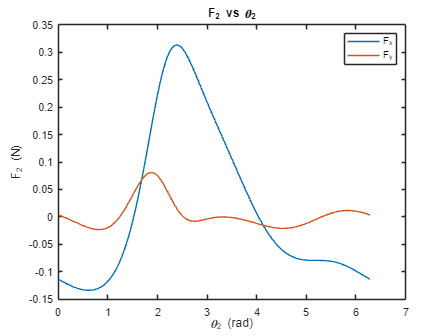

% Plotting joint forces
F12x = v(:, 1);
F12y = v(:, 2);
F23x = v(:, 3);
F23y = v(:, 4);
F34x = v(:, 5);
F34y = v(:, 6);
F3s = v(:, 7);
F14 = v(:, 8);
F56x = v(:,9);
F56y = v(:, 10);
F16x = v(:, 11);
F16y = v(:, 12);
M12 = v(:, 13);

% F12
figure(5)
plot(theta2, 10^-5*[F12x, F12y]);
xlabel("\theta_2 (rad)");
ylabel("F_1_2 (N)");
title("F_1_2 vs \theta_2");
legend("F_1_2_x", "F_1_2_y")

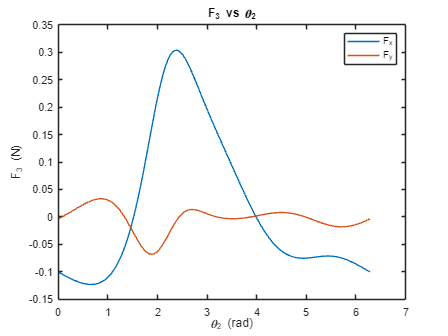

%F23
figure(6)
plot(theta2, 10^-5*[F23x, F23y]);
xlabel("\theta_2 (rad)");
ylabel("F_2_3 (N)");
title("F_2_3 vs \theta_2");
legend("F_2_3_x", "F_2_3_y")

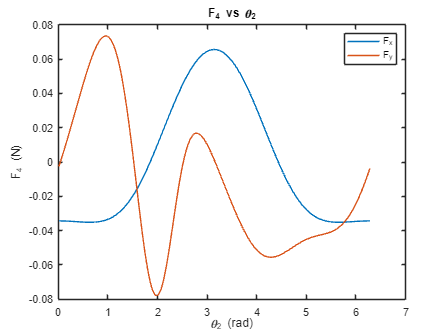

%F34
figure(7)
plot(theta2, 10^-5*[F34x, F34y]);
xlabel("\theta_2 (rad)");
ylabel("F_3_4 (N)");
title("F_3_4 vs \theta_2");
legend("F_3_4_x", "F_3_4_y")

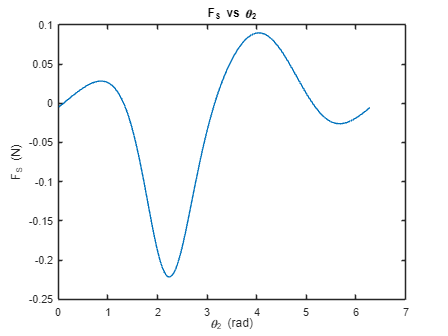

%F3S
figure(8)
plot(theta2, 10^-5*F3s);
xlabel("\theta_2 (rad)");
ylabel("F_3_S (N)");
title("F_3_S vs \theta_2");

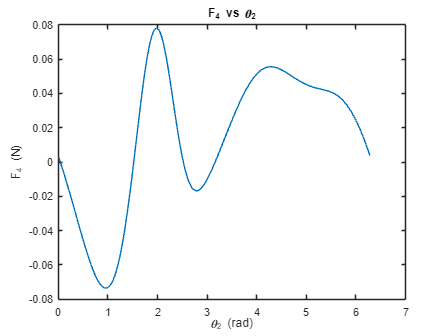

%F14
figure(9)
plot(theta2, 10^-5*F14);
xlabel("\theta_2 (rad)");
ylabel("F_1_4 (N)");
title("F_1_4 vs \theta_2");

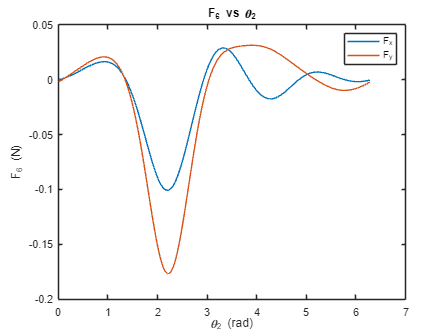

%F56
figure(10)
plot(theta2, 10^-5*[F56x, F56y]);
xlabel("\theta_2 (rad)");
ylabel("F_5_6 (N)");
title("F_5_6 vs \theta_2");
legend("F_5_6_x", "F_5_6_y");

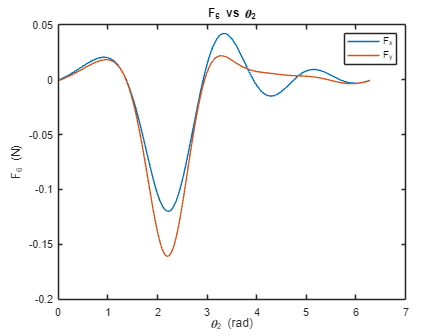

%F16
figure(11)
plot(theta2, 10^-5*[F16x, F16y]);
xlabel("\theta_2 (rad)");
ylabel("F_1_6 (N)");
title("F_1_6 vs \theta_2");
legend("F_1_6_x", "F_1_6_y");

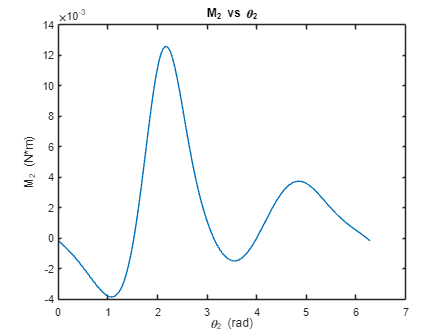


% Plotting moment
figure(12)
plot(theta2, 10^-7*M12)
xlabel("\theta_2 (rad)");
ylabel("M_1_2 (N*m)");
title("M_1_2 vs \theta_2");

## Shaking Force & Shaking Moment

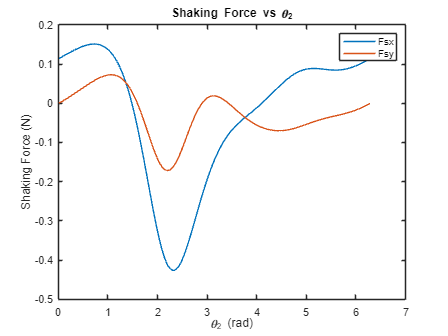

% Shaking forces in x and y
Fsx = -F12x + F16x;
Fsy = F12y - F14 + F16y;

% Shaking moment
Mso2 = M12 + F14.*transpose(r3) - F16y.*(-r7) - F16x.*(-r8);
Mso6 = I6.*transpose(d2theta6) + F12x.*(-r8) + F12y.*(-r7) + F14.*(transpose(r3) + r7);
Msl = F12y.*transpose(r3) + F16y.*(transpose(r3)+r7) + F16x.*(-r8);

% Plot shaking force
figure(13)
plot(theta2, 10^-5*[Fsx, Fsy]);
legend("Fsx", "Fsy")
title("Shaking Force vs \theta_2");
xlabel("\theta_2 (rad)")
ylabel("Shaking Force (N)")

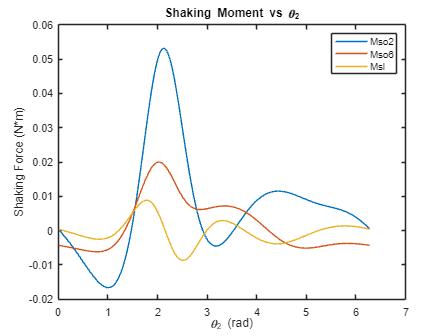


% Plot shaking moment
figure(14)
plot(theta2, 10^-7*[Mso2, Mso6, Msl]);
legend("Mso2", "Mso6", "Msl");
title("Shaking Moment vs \theta_2");
xlabel("\theta_2 (rad)")
ylabel("Shaking Force (N*m)")

## Coriolis Acceleration

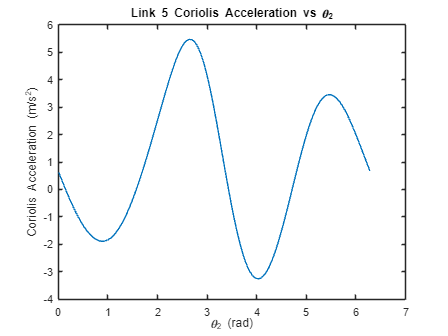

% Coriolis acceleration a = 2*v_radial*omega
acor = 2*d1r5.*d1theta4;

% Plot
figure(15);
plot(theta2, 10^-2*acor);
title("Link 5 Coriolis Acceleration vs \theta_2");
xlabel("\theta_2 (rad)")
ylabel("Coriolis Acceleration (m/s^2)");